# Section 1

Read in the data from "data2.csv". Note that this data contains:

- unit_code

- SPG Grade

- School Name

These three have not been dummy coded. They are part of the dataset for reference. You can drop these three before starting the analysis.

The response variable here is SPG Grade

data = readtable("data2.csv")

data = 440×146 table
    Var1    unit_code     student_num    lea_avg_student_num    Avg_Class_Size_Biology    Avg_Class_Size_EnglishII    Avg_Class_Size_MathI    Avg_Dist_Size_Biology    Avg_Dist_Size_EnglishII    Avg_Dist_Size_MathI    lea_total_expense_num    lea_salary_expense_pct    lea_benefits_expense_pct    lea_services_expense_pct    lea_supplies_expense_pct    lea_instruct_equip_exp_pct    lea_federal_perpupil_num    lea_local_perpupil_num    lea_state_perpupil_num    SPGGrade    SPGScore    EVAASGrowthScore    OverallAchievementScore    MathIScore    EnglishIIScore</

# Section 2:

Remove Var1, re-arrange columns such that unit_code, school name and SPG Grade are first 3 columns.

% remove Var1
data(:, 'Var1') = [];


% copy SPGGrade to spgGrade variable
% copy SchoolName to schoolName variable
spgGrade = data.SPGGrade;
schoolName = data.SchoolName;

% pop out these 2 variables from the table and added to the end
data(:, {'SPGGrade', 'SchoolName'}) = [];
data.SPGGrade = spgGrade;
data.SchoolName = schoolName;

% re-arrange these columns
data = data(:, [1 end end-1 2:end-2]);

% print first 10 rows
data(1:10, :)

ans = 10×145 table
    unit_code                SchoolName               SPGGrade    student_num    lea_avg_student_num    Avg_Class_Size_Biology    Avg_Class_Size_EnglishII    Avg_Class_Size_MathI    Avg_Dist_Size_Biology    Avg_Dist_Size_EnglishII    Avg_Dist_Size_MathI    lea_total_expense_num    lea_salary_expense_pct    lea_benefits_expense_pct    lea_services_expense_pct    lea_supplies_expense_pct    lea_instruct_equip_exp_pct    lea_federal_perpupil_num    lea_local_perpupil_num    lea_state_perpupil_num    SPGScore    EVAASGrowthScore    OverallAchievementScore    MathIScore  

# Section 3

Construct MLData which will be used for ML algorithms.

For classification and regression, you can try using MLData directly without preprocessing, i.e scaling.

For clustering, use scaledMLData

% copy data to MLData by removing first 2 columns
MLData = data(:, 3:end);

% store the class variable 
mldataClass = MLData.SPGGrade;

% pop out the class variable
MLData(:, 'SPGGrade') = [];

% Scale the data; Normalize it; use zscore
scaledMLData = zscore(MLData{:,:});

# Section 4: PCA 

Use clustering techniques to figure out if there are any natural patterns in the data. 

In order to do that, it will be beneficial to do a PCA to reduce the dimensions to aid in visualization of these clusters.

% Use PCA and visualize the first few components to see if there are any 
% natural patterns in the data.
% [pcs,scrs,~,~,pexp] = pca(measurements)
% pcs -> nxn matrix of principal components
% scrs -> A matrix containing the data transformed using the linear coordinate 
% transformation matrix pcs (first output).
% pexp -> A vector of the percentage of variance explained by each principal component.
[pcs, scrs, ~, ~, pexp] = pca(scaledMLData);

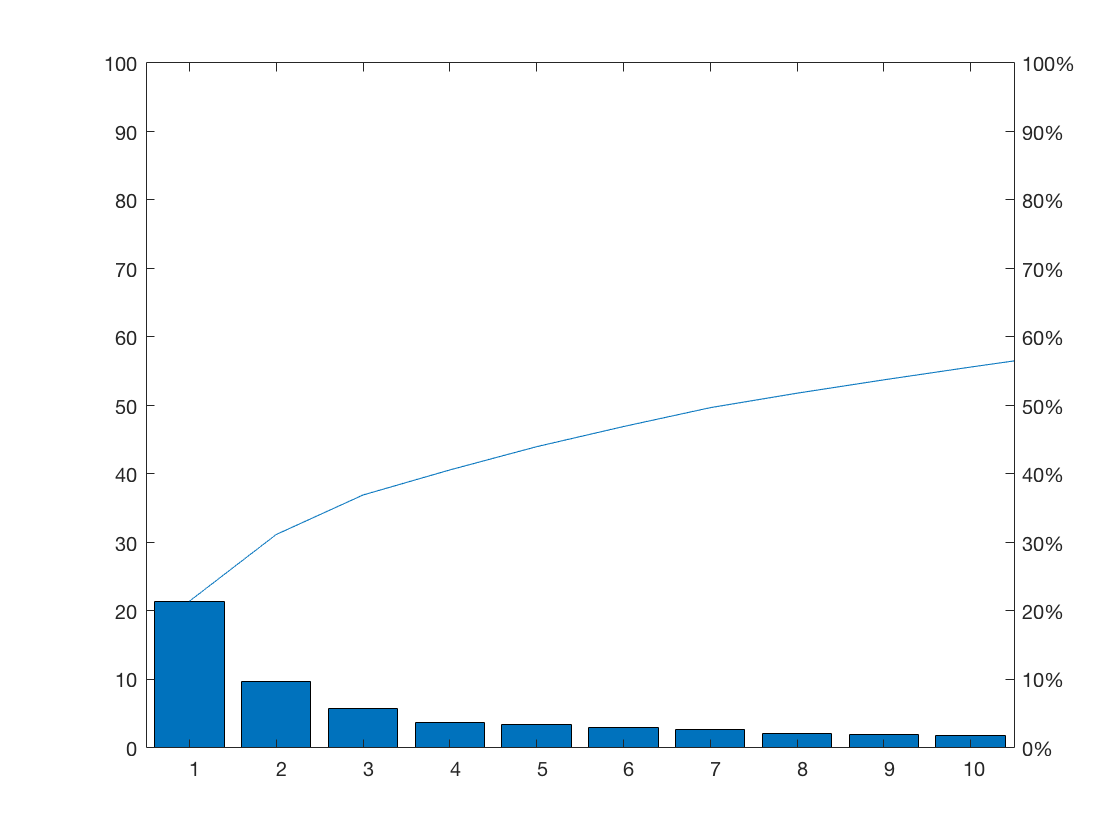


% draw a pareto plot
pareto(pexp);

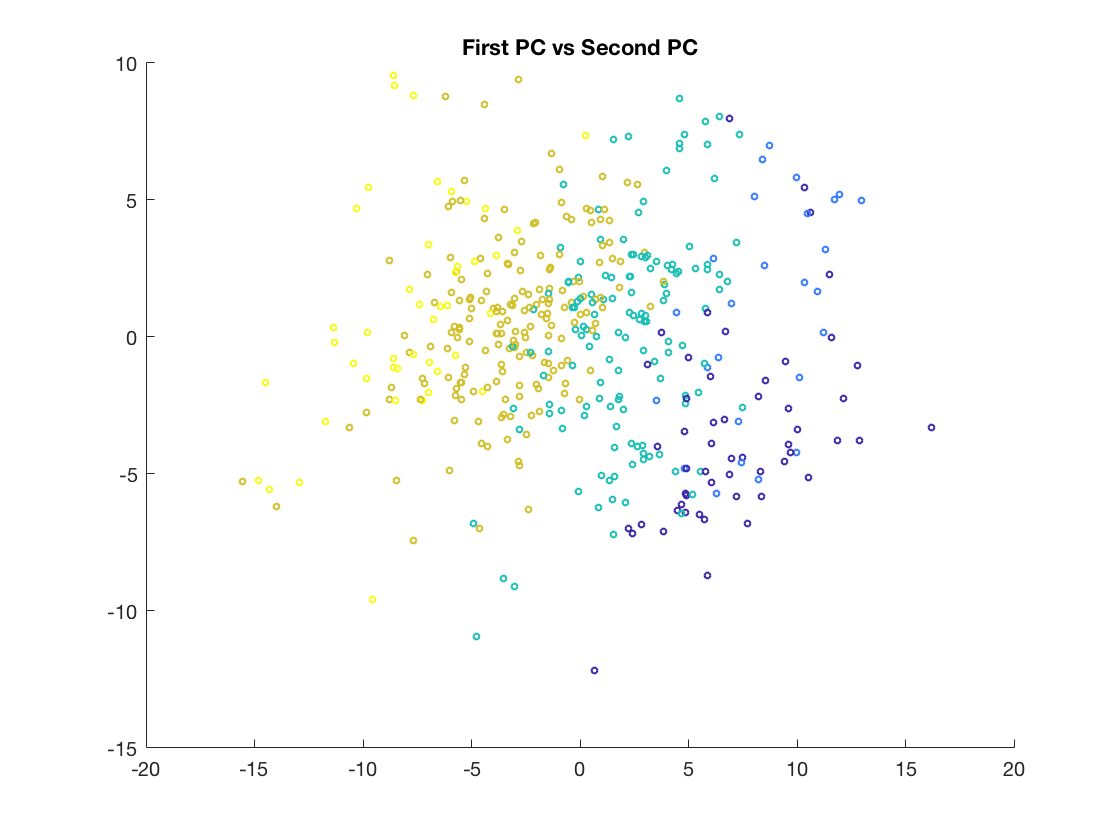


% convert the class variable to categorical variable
classVar = categorical(mldataClass);

% draw a scatter 2d plot to visualize first 2 components
scatter(scrs(:,1), scrs(:, 2), 10, classVar)
%legend('A', 'A+NG', 'B', 'C', 'D');
title('First PC vs Second PC');

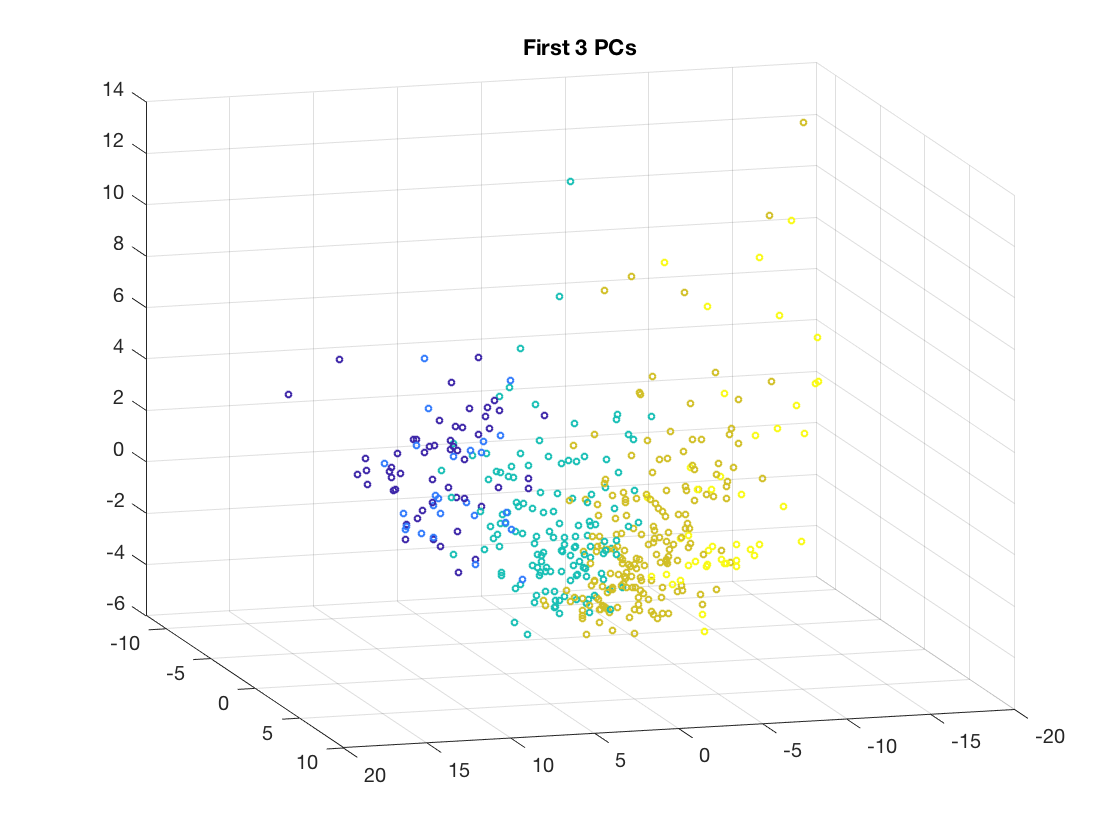


% draw a scatter 3d plot to visualize first 3 components
scatter3(scrs(:,1), scrs(:, 2), scrs(:,3), 10, classVar);
%legend('A', 'A+NG', 'B', 'C', 'D');
title('First 3 PCs');

view([163.6 15.0])

# Section 5: Clustering

K-Means is more useful when we have some knowledge of the number of groups in our data. Nevertheless, we can still use k-means and find the optimal number of clusters in the data.  Visualizing the data can also help you identify the number of groups. Having decided the number of groups to form, you can use the *k*-means clustering method to divide the observations into groups or clusters.

Let's assume there are 5 clusters.

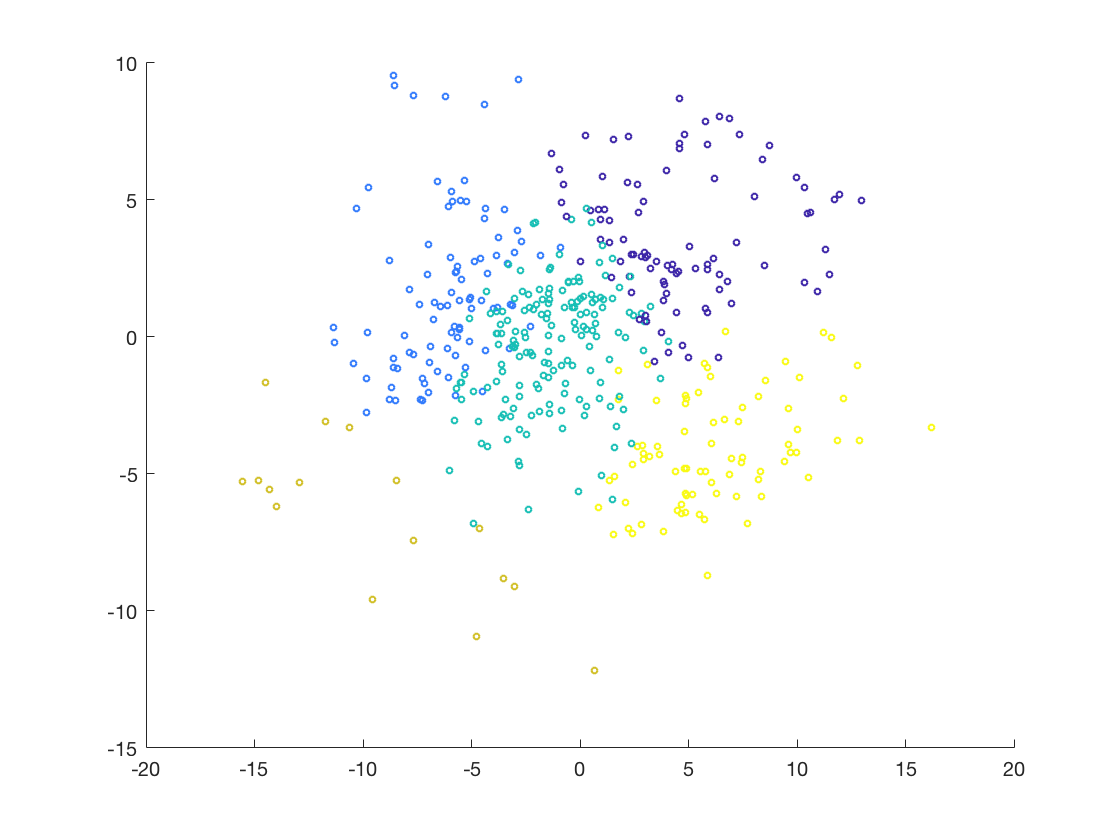

km = kmeans(scaledMLData, 5, 'Replicates', 5);

% plot the clusters using principal components
scatter(scrs(:,1), scrs(:,2), 10, km);

%view([163.6 11.2])

## Silhouette plot

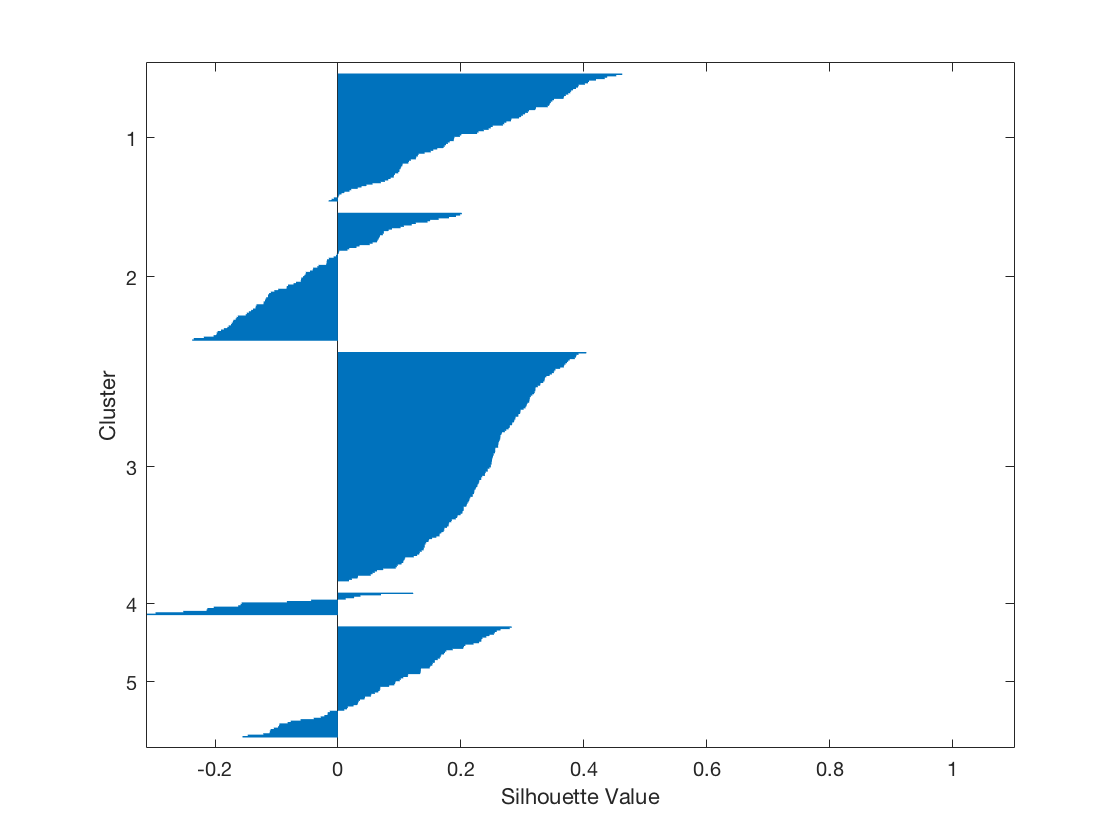

% Create a silhoutte plot of kmeans with 5 clusters
silhouette(scaledMLData, km);

## Evalclusters

% use evalclusters to figure out the optimal number of clusters
clustEv = evalclusters(scaledMLData, 'kmeans', 'silhouette', 'KList',2:6)

clustEv =   SilhouetteEvaluation with properties:

    NumObservations: 440
         InspectedK: [2 3 4 5 6]
    CriterionValues: [0.2286 0.1443 0.1508 0.1242 0.1459]
           OptimalK: 2


# Section 6:  Hierarchical Clustering

## Hierarchical Clustering

With hierarchical clustering, you can explore the *sub-clusters* that were grouped together to form bigger clusters.

## Step 1 – Determine Hierarchical Structure

The `linkage` function calculates the distance between each pair of points and, using these distances, determines the tree hierarchy by linking together pairs of “neighboring” points:

The optional [second and third input argument ](http://www.mathworks.com/help/stats/linkage.html?searchHighlight=linkage#inputarg_method)represent the method of finding the distance between the clusters (default - `'single'`) and to specify the distance metric (default - `'euclidean'`).

You can use the `dendrogram` function to visualize the hierarchy.

## Step 2 – Divide Hierarchical Tree into Clusters

You can use the `cluster` function to assign observations into groups, according to the linkage distances `Z`.

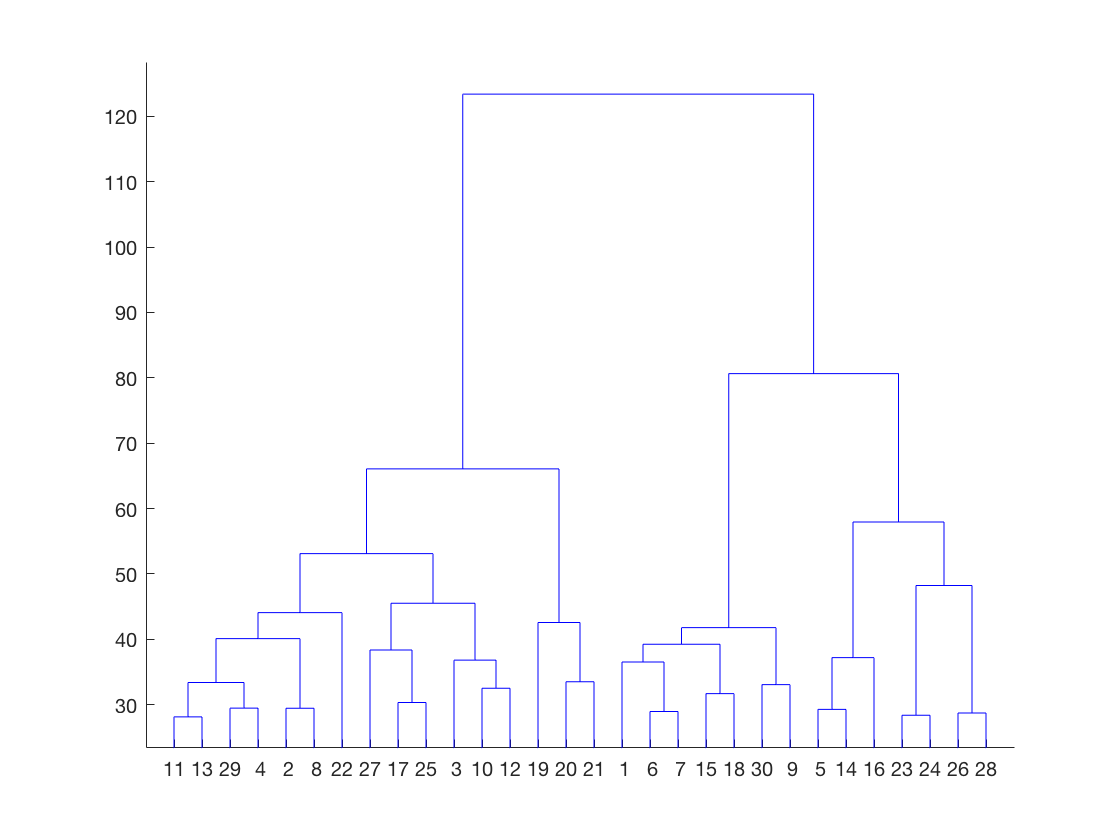

% Use the linkage function to encode a tree of hierarchical clusters from a set of observations
Z = linkage(scaledMLData,'ward');
dendrogram(Z)


% Use cluster function to assign observations into groups according to the linkage distances Z.
hgrps = cluster(Z, 'maxclust', 5);

The Cophenetic correlation coefficient quantifies how accurately the tree represents the distances between observations.

 Values close to 1 indicate a high-quality solution.  

pairwiseDist = pdist(scaledMLData);
ccc = cophenet(Z, pairwiseDist)

ccc = 0.2994

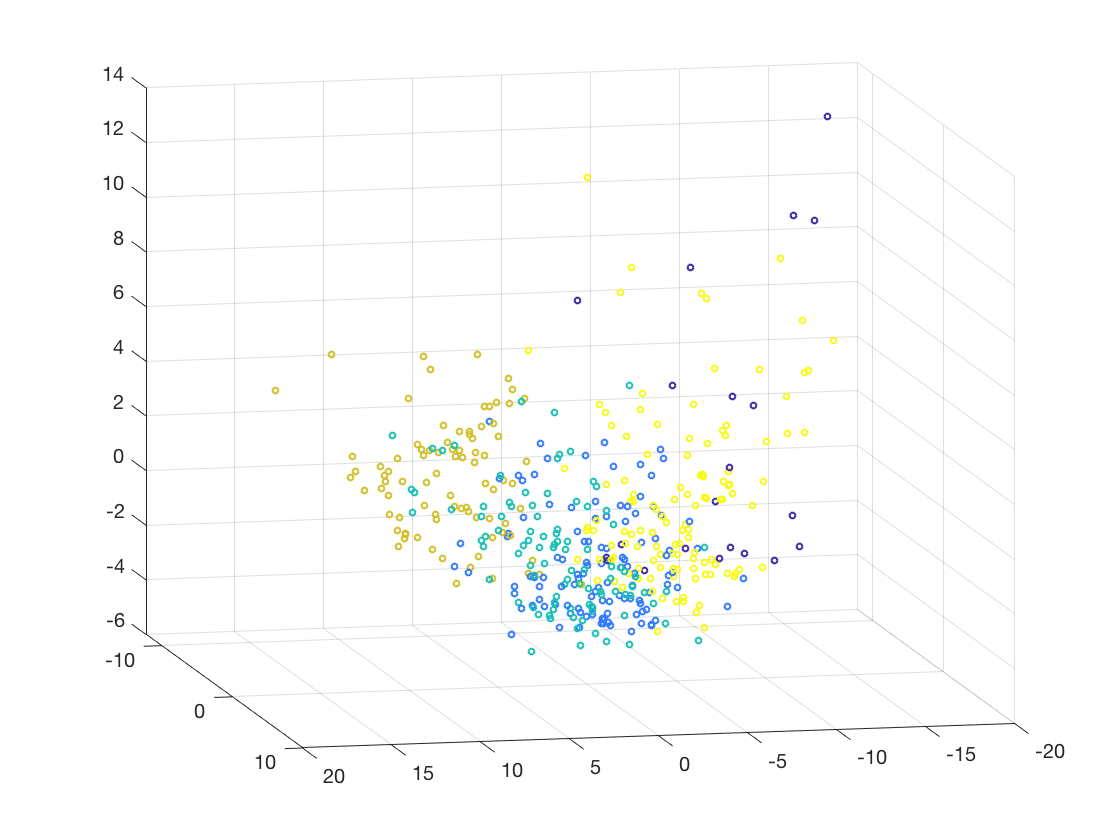

gmModel = fitgmdist(scaledMLData,5,'Replicates',5,'RegularizationValue',0.02);
[grp,~,gprob] = cluster(gmModel,scaledMLData);

%% View data
% Visualize groups
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,grp)
view([167.6 12.0])

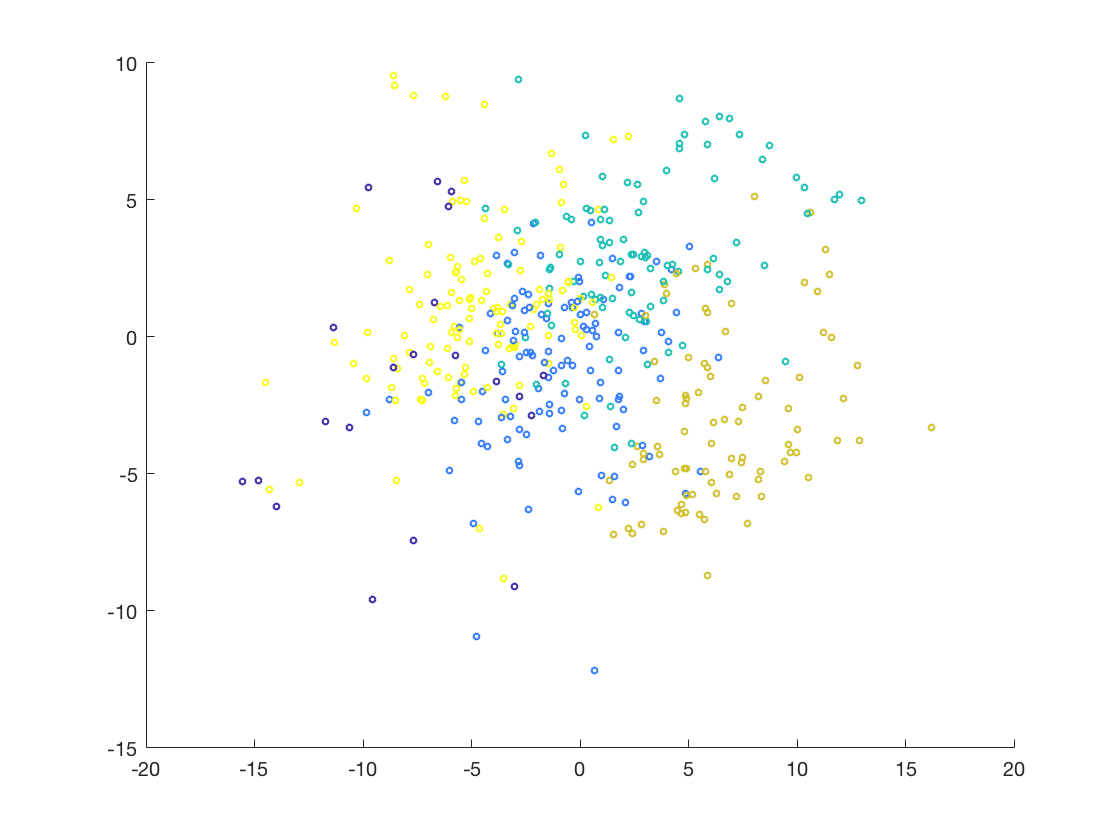

scatter(scrs(:,1),scrs(:,2),10,grp)

# Section 7: Prepare data for classification

Preparing the data for classification models.  Note that we have unit_code, school_name and our response variable "SPG Grade" in the original dataset **data.**

% copy data to clData by removing first 2 columns
% Retain the response variable "SPG Grade"
clData = data(:, 3:end);

% split the data in training and test sets
% Create the cvpartition variable
pt = cvpartition(clData.SPGGrade,'HoldOut',0.2);

% Create the training and test tables
clTrain = clData(training(pt),:);
clTest = clData(test(pt),:);

%% Display properties about the split
disp([num2str(height(clData)),' original observations split into:'])

440 original observations split into:


disp([' + ',num2str(height(clTrain)),' training observations'])

 + 352 training observations


disp([' + ',num2str(height(clTest)),' test observations'])

 + 88 test observations


# Section 8: Fit a classifier

MATLAB provides fitting functions for several learning algorithms. These function names take the form `fitc``*` where `*` represents the kind of learning algorithm.

For example, the following line of code will fit a *k*-nearest neighbor (*k*-NN) model to the training data.

`knnModel` `=` `fitcknn``(``trainData``,``'responseVarName'``)`

## Scale the data before feeding it to KNN

% make a copy of clTrain and clTest
scaledCLData = clTrain;
scaledCLTestData = clTest;

% Scale the training data; Normalize it; use zscore
scaledCLData{:,2:end} = zscore(clTrain{:,2:end});

% Fit a knn model
knnModel = fitcknn(scaledCLData, 'SPGGrade');

% Scale the test data; Normalize it; use zscore
scaledCLTestData{:,2:end} = zscore(clTest{:,2:end});

% Predict
predictedGroups = predict(knnModel, scaledCLTestData);

# Section 9: Evaluating the classification model

Evaluating the accuracy of the model can help in choosing the model that generalizes well to the unknown data. Evaluate the models by answering the following questions. 

- What metric and data should be used to evaluate the accuracy of the model?

- Should we consider the model's misclassification rate for individual classes? (Misclassifying sick people as healthy can have a higher cost than misclassifying healthy people as sick.)

You can measure the training error (resubstitution loss) using the function `resubLoss`.

% Calculate the validation error
testErr = loss(knnModel, scaledCLTestData)

testErr = 0.4664

## Confusion Matrix

You can find out the distribution of all predicted responses and how they compare to their true classes by calculating the confusion matrix.

cm= confusionmat(scaledCLTestData.SPGGrade, predictedGroups)

cm =     13     7     6     0     2
     4     3     0     0     3
     7     0    27     2     0
     0     0     8     1     0
     0     2     0     0     3


# Section 10: Use classification learner app